clc
clear all

Fc = 60; %frequency 60Hz
Av =1;  % amplitude
Ts = 0.0005; % 1/0.0005 = 2 kHz  campionamento
StopTime = 0.1;             % seconds
t = (0:Ts:StopTime-Ts)';     % seconds
omega = 2*pi*Fc; % angular frequency constant over time

%============= Model is at steady state ===========
A =  [1 0; 0 1]; % valori paper: A = eye(2);
B = [0;0]; % valori paper: B = 0;
C =  [cos(omega*t), -sin(omega*t)];  % frequenza di 60Hz
D = 0;

%se x1(0)= A*cos(phi) = x2(0)= A*sin(phi) --> phi = 45°
% x1 = 1*cos(pi/4);     %x1 = Av*cos(phi);
% x2 = 1*sin(pi/4);     %x2 = Av*sin(phi);
% x = [x1;x2];
Av = 1;
signal = Av*cos(omega*t)*cos(pi/4) - Av*sin(omega*t)*sin(pi/4); % y (outout plant)

Q = eye(2); %state noise covariance
R = 1;  % measurement noise covariance

% SIGNAL WITHOUT NOISE
filtered0 = funzioneBella(signal, Q, R, 0.1);
% figure(1)
% plot(t, signal, 'green', t, filtered0, 'red');
% ylim([-1.5,1.5]);
% grid on;

[filtered0, residue0, covariance0, p0] = funzioneBella(signal, Q, R, 0.1);

%residuo: r(t) = y(t)-y_hat(t|t-1)
% g = r'*cov(r)*r
% g0 = calcola_g(covariance0, residue0);


% SIGNAL WITH NOISE
%add a random noise on the signal
signal_disturbed = signal + 0.02 * randn(size(signal)); 

[filtered, residue, covariance, p] = funzioneBella(signal_disturbed, Q, R, 0.1);
figure(1)
subplot(211)
plot(t, signal_disturbed, 'blue', t, filtered', 'red');
ylim([-1.5,1.5]);
legA = legend('estimated','real');
set(legA,'FontSize',12)
title('chi detector without attack');grid on;

g = calcola_g(covariance, residue); %???
r = signal_disturbed - filtered' ;
g_prova = r'*inv(cov(residue))*r;


figure(1)
subplot(212)
plot(t, g );
ylim([-0.5,4]);
yline(3,'-','Threshold');

% Check if the fault changes the residual (lo fa il prof, senza attacco è 0
% con attacco è 1
isequal(residue0, residue) 

ans = logical
   0


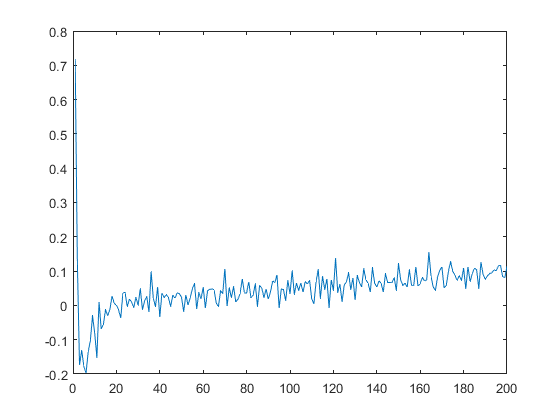


% figure(4)
% rng('default')
% rnds = residue';
% trnd = t';
% fnc = rnds + trnd;
% plot(fnc)

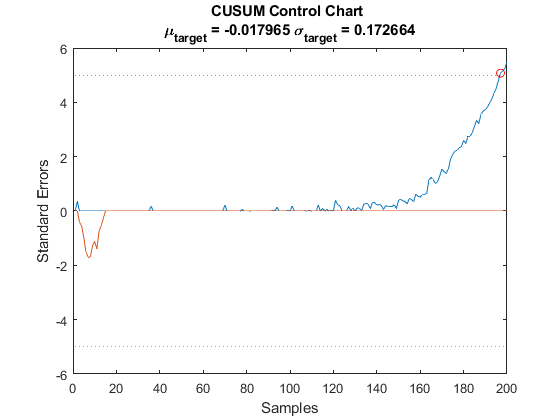

% cusum(fnc)

Add a  FDIA - Random case (without selecting tau)

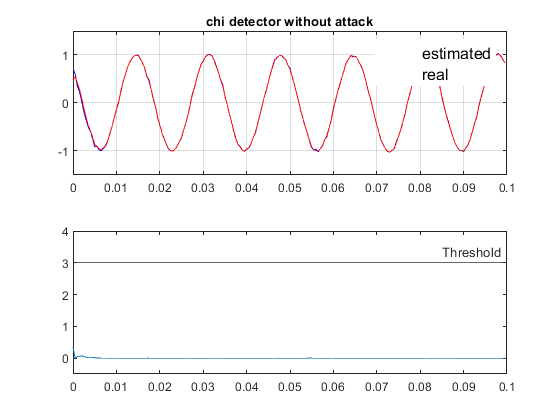

% signal_attacked = signal_disturbed + ya
y = signal_disturbed; 
y_sfasato = Av*cos(omega*t - pi/6);
j = 2;
for i=100:199
    y(i) = (j)*y_sfasato(i);
    j=j-0.01;
end

[filtered_a, residue_a, covariance_a, p_a] = funzioneBella(y, Q, R, 0.1);
figure(3)
subplot(211)
plot(t, signal_disturbed, 'blue', t, filtered_a, 'red');
ylim([-2,2]);
set(legA,'FontSize',12)

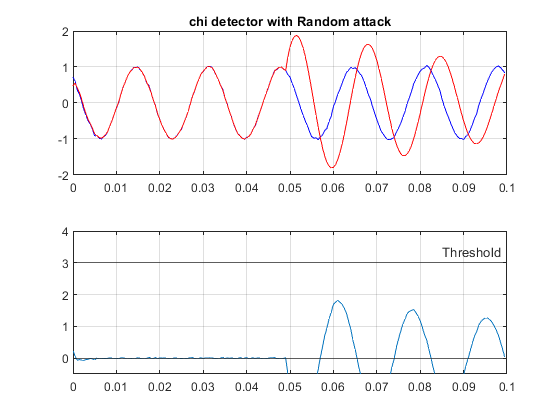

title('chi detector with Random attack');grid on;

r_a = signal_disturbed - filtered_a';

g_a = calcola_g(covariance_a, residue_a);

figure(3)
subplot(212)
plot(t, r_a);
ylim([-0.5,4]);
yline(0,'-');
yline(3,'-','Threshold');
grid on;


% Check if the fault changes the residual
isequal(residue, residue_a) 

ans = logical
   0


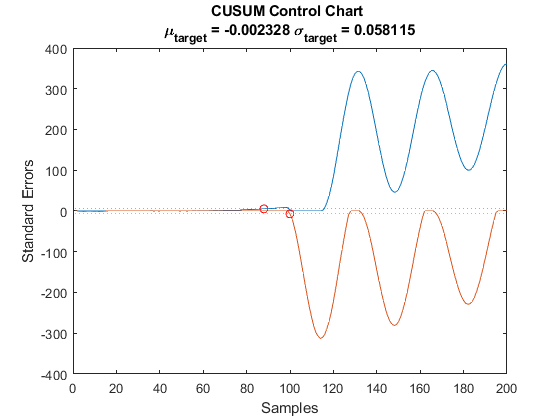


% figure(5)
% rng('default')
% rnds = r_a';
% trnd = t';
% fnc_a = rnds + trnd;
% cusum(fnc_a)

Consider now an attack vector of the form a=Hc which is undetectable by a standard BDD.

We choose a vector c in such a way to change the angle while remaining under the treshold

% %choose an angle of pi/3
% %from paper ya(n+t)= ya(t) - (lamba^(i+1))/M *y_star
% 

% % function [signal_attacked] = addAttack(signal,residue)
% % v = [0;1];
% % lambda = 1;
% % y_star = C*v;
% % n = 2; %dimension of state space
% % ya = zeros(size(signal));
% % y = signal + ya;
% % z = residue; %not attacked
% % 
% % Q = eye(2); %state noise covariance
% % R = 1;  % measurement noise covariance
% % [filtered_a, residue_a] = funzioneBella(y, Q, R, 0.1);
% % za = residue;
% %     while i<= max(size(signal))   %tempo 
% %         ya(n+i) = ya(i) - ((lambda)/M)*y_star;
% % 
% % 
% % 
% % 
% % norm_r = sqrt(residue'*residue)          % Norm of the residual
% % M = max(norm)
% %     end
% % end



functions:

function [g] = calcola_g(covariance, residue)
c = cov(covariance);
g = zeros(size(residue));

for i=1:length(residue)-1
    g(i) = residue(i:i+1)' * c  * residue(i:i+1); 
end
g(200) = residue(199:200)' * c  * residue(199:200); 
end
